# Introduction to fluid mechanics

[⇦ Overview](matlab:open('./Overview.m'))

Fluids are continuous material composed of a very large number of particles that do not display a fixed shape. Liquids and gases both display this characteristic with one major difference. Gases tends to occupy all of the volume that is available to them, while liquid tends to occupy a fixed volume. 

How can we study the statics and dynamics of such complex system? What kinf of forces are in action?

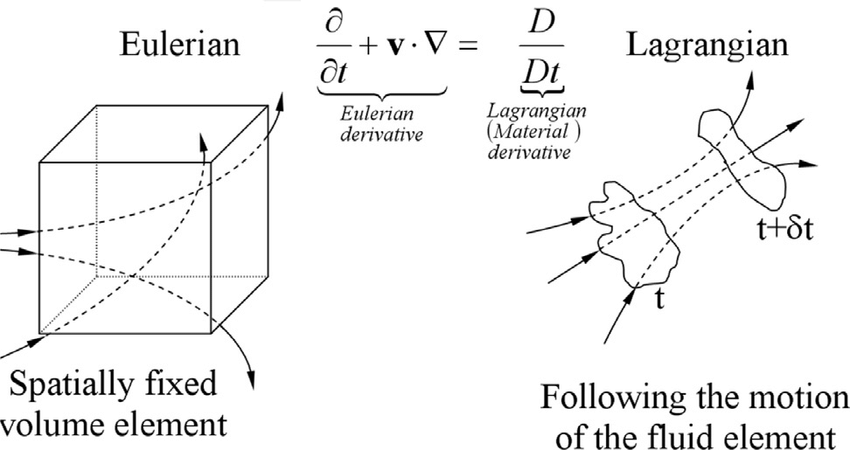

Fluid mechanics is the study of fluid at rest (statics) and fluid in motion (dynamics), their characteristics and the forces in action in those systems.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

`Icon that can be used`

  **Try**.   **Pro-tip**. ** Demonstration**.  **Reflect**. ** Application.**

## Notation

Before to get started on this introduction to fluid mechanics, we should define some nomenclature of the mathematical notation that will be in use in this module. The mathematical concept used in this module includes (non-exhaustive): partial derivative, derivation operator (gradient, Laplacian), vector calculus, multivariable function calculus, integral of volume, surface and line intergral.

The partial would be expressed using the following equations for a function $f\left(x,y\right)$:

$\frac{\partial f\;}{\partial x}=\lim_{h\to 0} \frac{\;f\left(x+h,y\right)-f\left(x,y\right)}{h}$  and  $\frac{\partial f\;}{\partial u}=\lim_{h\to 0} \frac{\;f\left(x,y+h\right)-f\left(x,y\right)}{h}$.

The gradient operator nabla is defined as followed:

$\nabla_{1D} \equiv \frac{\;\partial \;}{\partial x\;}$;  $\nabla_{2D} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial x\;}\\
\frac{\;\partial \;}{\partial y}
\end{array}\right\rbrack }_{\textrm{carthesian}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial }{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}
\end{array}\right\rbrack }_{\textrm{polar}}$; $\nabla_{3D} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial x\;}\\
\frac{\;\partial \;}{\partial y}\\
\frac{\;\partial }{\partial z}
\end{array}\right\rbrack }_{\textrm{carthesian}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial }{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}\\
\frac{\;\partial \;}{\partial z}
\end{array}\right\rbrack }_{\textrm{cylindrical}} \equiv {\left\lbrack \begin{array}{c}
\frac{\;\partial \;}{\partial r}\\
\frac{\;1}{r}\frac{\;\partial \;}{\partial \theta \;}\\
\frac{\;1}{\textrm{rsin}\left(\theta \;\right)}\frac{\;\partial \;}{\partial \varphi \;\;}
\end{array}\right\rbrack }_{\textrm{spherical}} \;$

These expression represent the nable operator for one, two and three dimensional coordinates system in carthesian but also polar, cylindrical and spherical system.

Lastly, vector such as the velocity of position vector will be represented using bold font over arrow superscript.


$$\mathit{\mathbf{u}}=\left\lbrack \begin{array}{c}
u_x \\
u_y \\
u_z 
\end{array}\right\rbrack$$


## Definition of fluid parcel

XXX Finish this definition and think of an example

also called fluid elements

A fluid parcels is an imaginary 

Condition are uniform in the fluid parcel

No specific size

**Motivating Example:**

## **Lagrangian specification of flow**

In Lagrangian flow theory, the flow is study by looking at the motion of the individual particle of fluids.

**Motivating Example: Ocean Drift barge**

Surface oceanic current are studied using barge that are left in the open to drift following the current. 

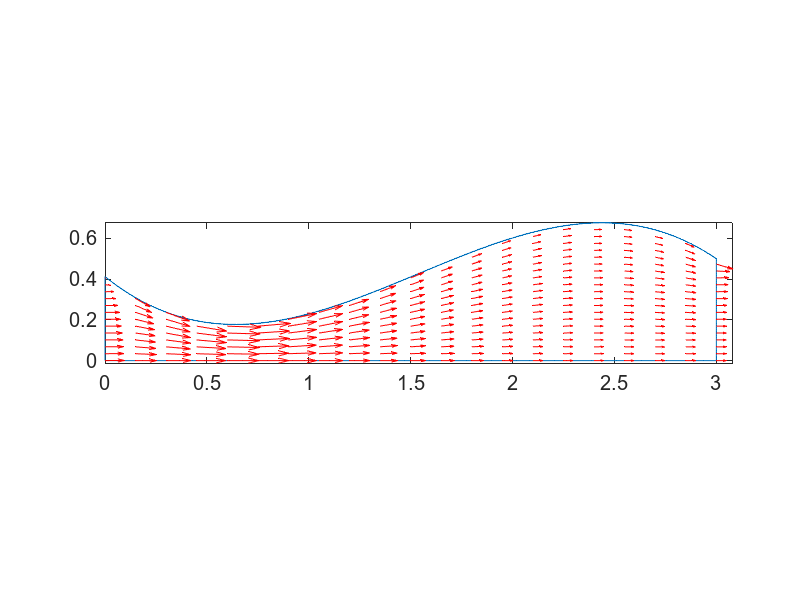

Error using drawnow
Unknown command option.

Error in fluidDefinition>plotDrifter (line 123)
        drawnow limirate

% Select a drifter
Platform = 4102654;
plotDrifter(Platform)

  **Reflect**. How well can you characterize the oceanic surface flow using Lagrangian method?

  **Pro-tip**. The line that are plotted here are called **pathline **they represent the line that a particle travelled through time.

## Eulerian specification of flow

In Eulerian flow theory, the flow is studied by looking at the evolution of physical parameter of the flow with respect to time at fixed point in space.

**Motivating Example: Ocean Buoy**

Bouy = 44032

Bouy = 44032

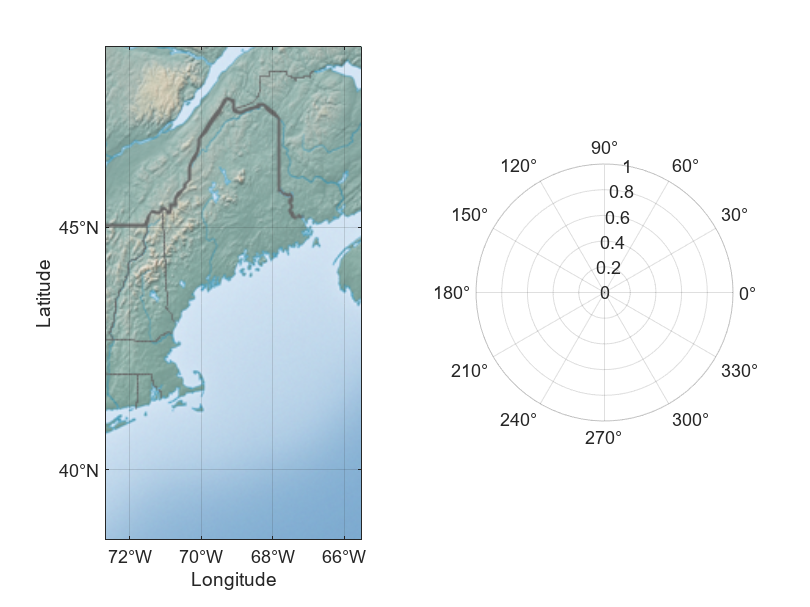

% Load the data
load BouysData.mat

% Get the location of the five bouys
[Bouys, iBouys, ~] = unique(bouy.BOUY);
iSelect = iBouys( Bouys == Bouy);

% Different color for the one that is selected

tl = tiledlayout(1,2);
ax1 = nexttile;
geoscatter(NaN,NaN);

geolimits([41.6 45.7],[-72.7 -65.5])
geobasemap colorterrain
% h1 = animatedline('LineStyle','none', 'Marker', 'o', 'MarkerSize', 6, ...
%                   'MarkerFaceColor', '#0072BD', 'MarkerEdgeColor', '#0072BD');
% h2 = animatedline('LineStyle','none', 'Marker', 'o', 'MarkerSize', 6, ...
%                   'MarkerFaceColor', '#D95319', 'MarkerEdgeColor', '#D95319');

nexttile
polarplot(NaN, NaN)


% pax = polaraxes;
% pax.ThetaDir = "clockwise";
% pax.ThetaZeroLocation = "top";
% % h = animatedline(pax, 'LineStyle', '-', 'LineWidth', 4);
% 
% title("Current direction from true north")
% 
% thetaticks(0:45:360)
% thetaticklabels({'N', 'NE', 'E', 'SE', 'S', 'SW', 'W', 'NW'})
% rticks([50 100 150]);
% rticklabels({'50 cm/s', '100 cm/s', '150 cm/s'})
% rlim([0 150])


% clearpoints(h1)
% addpoints(h1 ,bouy.LAT(iBouys), bouy.LON(iBouys));
% clearpoints(h2)
% addpoints(h2,  bouy.LAT(iSelect), bouy.LON(iSelect))
% 




% 
% subplot(1,2,1)
% load BouysData.mat
% [Bouys, iBouys, ~] = unique(bouy.BOUY);
% % Plot all the bouy in SeriesIndex 1
% geoscatter( bouy.LAT(iBouys), bouy.LON(iBouys), "filled", "SeriesIndex", 1)
% geolimits([39.9 46.2],[-73.2 -62.1])
% geobasemap colorterrain
% hold on
% 
% % Plot the bouy that is selected on SeriesIndex 2
% iSelect = iBouys( Bouys == Bouy);
% geoscatter( bouy.LAT(iSelect), bouy.LON(iSelect), "filled", "SeriesIndex", 2)
% hold off
% 
% % Reduce dataset to the selected bouy data:
% bouy = bouy( bouy.BOUY == Bouy, :);
% bouy = sortrows(bouy, "DATE", "ascend");
% for i = 1:size(bouy,1)
%     clearpoints(h)
%     addpoints(h,  [0 bouy.DIR01(i)], bouy.SPD01(i)*[0 1])
%     
%     drawnow limitrate
% end
drawnow

% Add area under the plot

## Link in between Eulerian and Lagrangian

% Step 1: define an unsteady 2D Eulerian flow
% Step 2: track a particle


## Pathline, Streakline, Streamline

% On the same 2D Eulerian flow
% Define and plot a pathline, which was done in the previous step
% Define and plot a streakline, by asking the student to click on a point
% Define and plot the streamline and plot it, path of massless particle

% Show what happen if the flow is steady
% Show what happen if the flow is uniform
% Show what happen if the flow is steady and uniform

## Material derivative

 **Reflect**. The second law of physics tell us $m\frac{\;\partial \mathit{\mathbf{u}}}{\partial t}=\mathit{\mathbf{F}}$

A    Phi(x,t)

B    Phi(x+u*dt, t+dt)

% syms Phi(x,t) u dx dt
% 
% dPhidt = limit( ( Phi(x+u*dt, t+dt) - Phi(x,t) )/dt, dt, 0 )



$$\frac{D\phi \;}{\textrm{Dt}}=\frac{\;\partial \phi \;}{\partial t}+\mathit{\mathbf{u}}\cdot \nabla \phi \;$$


% [graduxx, graduxy] = gradient(ux, 0.1);
% [graduyx, graduyy] = gradient(uy, 0.1);
% Ax = 0.0 + ux.*graduxx + uy.*graduxy;
% Ay = 0.0 + ux.*graduyx + uy.*graduyy;
% A  = sqrt(Ax.^2+Ay.^2);
% contourf(xg, yg, A , 256, 'LineColor', 'none')
% hold on
% quiver(xg, yg, Ax, Ay, 'Color', 'w')
% xlim([0 1])
% ylim([0 1])
% xlabel("x-location")
% ylabel("y-location")
% title("Total derivative of velocity")
% hold off

 **Reflect**.This acceleration is the acceleration felt by the particle of fluid in this field of velocity. Newton's law $m\vec{a} =\sum \vec{\;F_{\textrm{ext}\;} }$

Physical properties of the system such as temperature, mass, density, or really anything is hold on the fluid particle wether than the grid.

## Reynolds Transport Theorem

So far we discussed how to describe the motion of the fluid particle


$$\int(\nabla\cdot {\bf F})dV=\int ({\bf F}\cdot{\bf n})dS$$


1 - Derive the Reynolds transport therorem

2 - Ask to apply the theorem to mass -> conservation of mass

3 - Conservation of energy?

% 

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function plotDrifter(platform)
    
    load drifter.mat
   
    drifter = drifter( drifter.platform_code == platform, :);
    
    figure()
    geoaxes
    geolimits([23.7 43.5],[-91.6975 -61.3025])
    geobasemap colorterrain

    h = animatedline;
    for i = 1:size(drifter,1)
        addpoints(h, drifter.latitude(i), drifter.longitude(i))
        title(drifter.time(i))
        drawnow limirate
    end
    drawnow

end

[⇦ Return to the navigation page](matlab: OpenOverview)